# Nodel Anaysis

- *Electric Circuits Virtual Labs Project*

- *Author: Zekeriya Aliyazicioglu, Dennis Dahlquist*

- *Topic: Electrical Circuit Virtual Lab*

## Introduction

Nodal analysis methods can be universally applied to solve circuit problems. The nodal analysis method generates independent simultaneous equations by applying Kirchoff’s Current Law (KCL) at the unknown nodes of the circuit. The **aim of nodal analysis** is to determine the voltage at each node relative to the reference (or ground) node. Once we have done this we can easily work out these voltages to calculate voltages, currents, and power for every component in the circuit.

## Learning Objectives

Will be able write  node equations for an arbitrary circuit containing resistors and independent and dependent voltage and current sources and find the node voltages.

## Nodal Analysis

Nodal analysis is a method of finding all the unknown node voltages of a circuit to a ground (reference) node . The method is based on Kirchhoff’s current law (KCL). Nodes can be labeled 1, 2, 3,..., (0 can be used for the ground node), and voltages on these nodes can be labeled V1, V2, V3,..., The node voltage can be found as a ground node (0 V). If a voltage source is connected between a node and the ground, the node voltage is already known, and  do not need to find the node voltage on this node. A solution to the node voltages is obtained by solving the set of node-voltage equations. The nodal analysis provides voltages at all the nodes of the given circuit. 

### **Case 1 :** All voltage sources are not  connected between the nonreference node

We assume that all voltage sources are not  connected between the nonreference node. If there is a voltage source in a circuit between two nonreference nodes whose voltages are unknown and we do not know the current through the voltage source, we call it a supernode and we will solve under **Supernode** section

### Steps to Determine Node Voltages

- Select a node as the ground node 0. 

- Assign V1, V2, …Vn-1 to remaining n-1 nodes,  identifying any known voltages. . The voltages are referenced with respect to the ground node.

- Select a direction for the current passing through each resistor at the node with an unknown voltage and express the branch currents in terms of node voltages. 

- Apply KCL to each of the n-1 non-reference nodes. 

- Use Ohm’s law to express the branch currents in terms of node voltage

- Solve the resulting simultaneous equations to obtain the unknown node voltages.

Let’s take the steps by considering the circuit below: 

- The circuit below has four nodes. Let’s select the reference node (ground) to be the bottom node, which is given in this case.                   

                       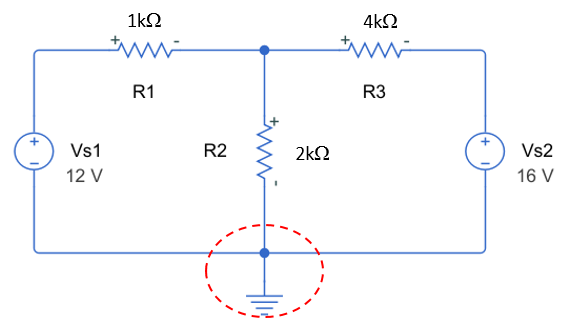

          2. Let’s label the remaining three nodes as V1, V2, and V3, as shown below:

                        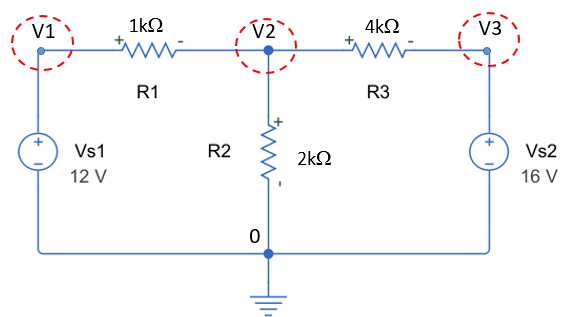

                Look at the figure above to find  any of the quantities  are known?

                           
$$V_1 =12V, V_2 =16V$$


            3. Let's select the direction for the current passing through each resistor at the node with an unknown voltage (node V2) shown below and write the branch  currents.

                           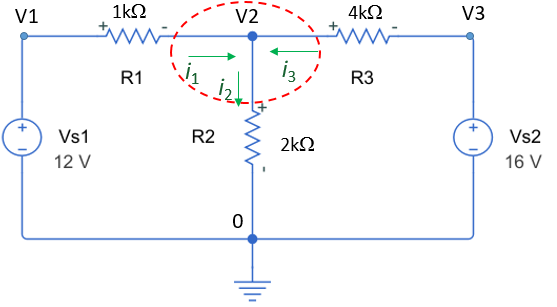

           4. Apply KCL at node V2

                                
$$i_1-i_2+i_3=0$$


           5. Let's write each of the branch currents in terms of node voltages. This is done by using Ohm’s Law (you have to be careful about the polarities).

                              $i_1 = \frac{V_1 -V_2 }{R_1}$,   or    $i_1 = \frac{12-V_2}{1k\Omega}$

                             $i_2 = \frac{V_2 -0 }{R_2}=\frac{V_2}{2k\Omega}$,    

                             $i_3 = \frac{V_3 -V_2 }{R_3}$       or     $i_3 =\frac{16-V_2}{4k\Omega}$

           6. Apply the branch currents equation to KCL at node 2.

                        $\frac{V_1-V_2}{R_1}-\frac{V_2}{R_2}+\frac{V_3-V_2}{R_3}=0$    or       $\frac{12-V_2}{1k\Omega}-\frac{V_2}{2k\Omega}+\frac{16-V_2}{4k\Omega}=0$

      This is one equation and one unknown. One of the methods to use MATLAB** solve** function to find V1 as follow.    

u = symunit;

% Given Values
Vs1 = 12*u.V;
Vs2 = 16*u.V;
R1 = 1000*u.Ohm;
R2 = 2000*u.Ohm;
R3 = 4000*u.Ohm;

% Known node voltages V1 and V2
V1 = Vs1;
V3 = Vs2;

% Unknown node voltage V2
syms V2;

% Node equation and solution
V2 = solve ((V1-V2)/R1-V2/R2+(V3-V2)/R3==0)

$$V2 = \frac{64}{7}\,V$$

Then, using the equations in step 5 to find the branch currents. Since resistors are $k\Omega$, the current values are expecting mA value 

% Find Currents
i1 = (V1-V2)/R1;
i1 = rewrite(i1,u.mA)   % define as mA

$$i1 = \frac{20}{7}\,\mathrm{mA}$$

i2 = V2/R2;
i2 = rewrite(i2,u.mA)   % define as mA

$$i2 = \frac{32}{7}\,\mathrm{mA}$$

i3 = (V3-V2)/R3;
i3 = rewrite(i3,u.mA)   % define as mA

$$i3 = \frac{12}{7}\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

V2 = vpa(V2,5)

$$V2 = 9.1429\,V$$

i1 = vpa(i1,5)

$$i1 = 2.8571\,\mathrm{mA}$$

i2 = vpa(i2,5)

$$i2 = 4.5714\,\mathrm{mA}$$

i3 = vpa(i3,5)

$$i3 = 1.7143\,\mathrm{mA}$$

An other method is to solve the last equation in step 6 manually by some simple algebra. Multiplication of this equation by 4000 yield. 

                        
$$4(12-V_2)-2V_2+(16-V_2)=0$$


    which can be simplified 

                          
$$V_2=\frac{64}{7}=9.143V$$


To make alternative simulation, we  can define the resistance values are as variables to see the effects on the node voltages and branch currents through the resistance.

u=symunit;

% Given Values
Vs1 = 12*u.V;
Vs2 = 16*u.V;
R1 = 1*u.kOhm;
R1 =5*u.kOhm %Range 1kOhms - 10kOhms

$$R1 = 5\,\mathrm{k\Omega}$$

R2 =9*u.kOhm %Range 1kOhms - 20kOhms

$$R2 = 9\,\mathrm{k\Omega}$$

R3 =4*u.kOhm %Range 1kOhms - 10kOhms

$$R3 = 4\,\mathrm{k\Omega}$$


% Known node voltage V1 and V2
V1 = Vs1

$$V1 = 12\,V$$

V3 = Vs2

$$V3 = 16\,V$$


% Unknown V2
syms V2;
% Node equation and solution
V2 = solve ((V1-V2)/R1-V2/R2+(V3-V2)/R3==0)

$$V2 = \frac{1152}{101}\,V$$


% Find Currents
i1 = (V1-V2)/R1;
i1 = rewrite(i1,u.mA)

$$i1 = \frac{12}{101}\,\mathrm{mA}$$

i2 = V2/R2;
i2 = rewrite(i2,u.mA)

$$i2 = \frac{128}{101}\,\mathrm{mA}$$

i3 = (V3-V2)/R3;
i3 = rewrite(i3,u.mA)

$$i3 = \frac{116}{101}\,\mathrm{mA}$$

Display each values in decimal number

V2 = vpa(V2,5)

$$V2 = 11.406\,V$$

i1 = vpa(i1,5)

$$i1 = 0.11881\,\mathrm{mA}$$

i2 = vpa(i2,5)

$$i2 = 1.2673\,\mathrm{mA}$$

i3 = vpa(i3,5)

$$i3 = 1.1485\,\mathrm{mA}$$

Circuit can be simulated  in MATLAB Simulink [./Simulink\Node_Analysis_1.slx](matlab:open('./Simulink\Node_Analysis_1.slx'))

        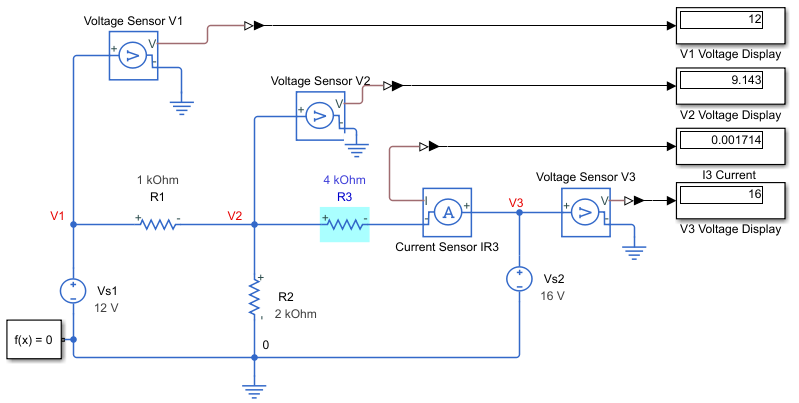

#### Example 1. Node analysis with voltage sources connected to reference node

Writing node analysis to find node voltages $$V_2, V_3$, voltage cross resistor  $R_3$, and  current through $R_5$

                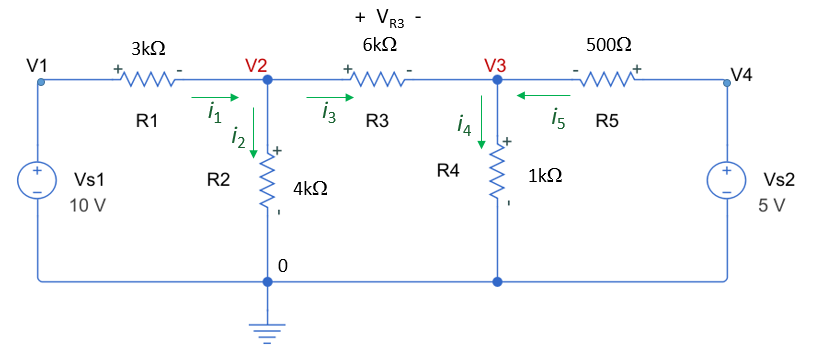

   **Solution**

    Steps 1, 2, and 3 is  given in the figure above. We can look at the figure to find any of the nodes voltages are known.

                           $V_1 =V_{s1}=10V$  and $V_4 =V_{s2}=5V$

     4.  Apply KCL at unknown nodes 2 and 3

                                $i_1-i_2-i_3=0$     and     $i_3-i_4+i_5=0$ 

      5. Let's write each of the branch currents in terms of node voltages. This is done using Ohm’s Law (you have to be careful about the polarities).

                        $i_1 = \frac{V_{s1} -V_2 }{R_1}=\frac{12-V_2}{3k\Omega}$,      $i_2 = \frac{V_2 -0 }{R_2}=\frac{V_2}{4k\Omega}$,     $i_3 = \frac{V_2 -V_3 }{R_3}= \frac{V_2 -V_3 }{6k\Omega}$,  

                         $i_4 = \frac{V_3  }{R_4}= \frac{V_3 }{1k\Omega}$,           $i_5 = \frac{V_{s2} -V_3 }{R_5}= \frac{5 -V_3 }{500\Omega}$

       6. Apply the branch currents equation to KCL equations at unknown nodes 2 and 3.

                 At node 2           $\frac{V_{s1}-V_2}{R_1}-\frac{V_2}{R_2}-\frac{V_2-V_3}{R_3}=0$     or   $\frac{10-V_2}{3k\Omega}-\frac{V_2}{4k\Omega}-\frac{V_2-V_3}{6k\Omega}=0$

                At Node 3           $\frac{V_2-V_3}{R_3}-\frac{V_3}{R_4}+\frac{V_{s2}-V_3}{R_5}=0$     or   $\frac{V_2-V_3}{6k\Omega}-\frac{V_3}{1k\Omega}+\frac{5-V_3}{500\Omega}=0$

There are two unknowns and  two equations. Use MATLAB solve function to find unknown voltages V2 and V3  as follow.   

u = symunit;

% Given Values
Vs1 = 10*u.V;
Vs2 = 5*u.V;
R1 = 3*u.kOhm;
R2 = 4*u.kOhm;
R3 = 6*u.kOhm;
R4 = 1*u.kOhm;
R5 = 500*u.Ohm;

%Known node voltage V1 and V2
V1 = Vs1;
V4 = Vs2;

%Unknown node voltage V2 and V3
syms V2 V3;
%Node equation and solution
[V2,V3] = solve ((V1-V2)/R1-V2/R2-(V2-V3)/R3==0, (V2-V3)/R3-V3/R4+(V4-V3)/R5==0);
V2 = rewrite(V2,u.V)

$$V2 = \frac{880}{169}\,V$$

V3 = rewrite(V3,u.V)

$$V3 = \frac{580}{169}\,V$$


% Find voltage cross resistor R3 and current i5 through resistor R5
i3 = (V2-V3)/R3;
VR3 = i3*R3

$$VR3 = \frac{300}{169}\,V$$

i5 = (V4-V3)/R5;
i5 = rewrite(i5,u.mA)

$$i5 = \frac{530}{169}\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

V2 = vpa(V2,5)

$$V2 = 5.2071\,V$$

V3 = vpa(V3,5)

$$V3 = 3.432\,V$$

VR3 = vpa(VR3,5)

$$VR3 = 1.7751\,V$$

i5 = vpa(i5,5)

$$i5 = 3.1361\,\mathrm{mA}$$

Also, Last two equations in step 6 can be solved manually with some simple algebra. The equations can be rearranged  in unknown variables and put into a matrix form as

            $\left[ \begin{array} { c c } { -(\frac{1}{R_1}+\frac{1}{R_2}+\frac{1}{R_3}) } & {\frac{1}{R_3} } \\ { \frac{1}{R_3} } & {-(\frac{1}{R_3}+\frac{1}{R_4}+\frac{1}{R_5}) } \end{array} \right] \left[ \begin{array} { l } { V _ 2 } \\ { V _ 3 } \end{array} \right] = \left[ \begin{array} { c } { -\frac{V_{s1}}{R_1}} \\ {- \frac{V_{s2}}{R_5} } \end{array} \right]$  or     $\left[ \begin{array} { c c } { -(\frac{1}{3k}+\frac{1}{4k}+\frac{1}{6k}) } & {\frac{1}{6k} } \\ { \frac{1}{6k} } & {-(\frac{1}{6k}+\frac{1}{1k}+\frac{1}{500}) } \end{array} \right] \left[ \begin{array} { l } { V _ 2 } \\ { V _ 3 } \end{array} \right] = \left[ \begin{array} { c } { -\frac{12}{3k}} \\ {- \frac{5}{500} } \end{array} \right]$

This matrix equation can be solved using MATLAB as shown

%Matrix AxV=b
A = [-(1/R1+1/R2+1/R3) 1/R3; 1/R3 -(1/R3+1/R4+1/R5)]

$$A = \left(\begin{array}{cc} -\frac{3}{4}\,\frac{1}{\mathrm{k\Omega}} & \frac{1}{6}\,\frac{1}{\mathrm{k\Omega}}\\ \frac{1}{6}\,\frac{1}{\mathrm{k\Omega}} & -\frac{1}{500}\,\frac{1}{\Omega }-\frac{7}{6}\,\frac{1}{\mathrm{k\Omega}} \end{array}\right)$$

b = [-Vs1/R1; -Vs2/R5]

$$b = \left(\begin{array}{c} -\frac{10}{3}\,\frac{V}{\mathrm{k\Omega}}\\ -\frac{1}{100}\,\frac{V}{\Omega } \end{array}\right)$$

V = A\b;

V2 = V(1);
V2 = rewrite(V2,u.V)

$$V2 = \frac{880}{169}\,V$$

V3 = V(2)

$$V3 = \frac{5\,\left(2000\,\Omega +27\,\mathrm{k\Omega}\right)}{15250\,\Omega +27\,\mathrm{k\Omega}}\,V$$

V3 = simplify(V3)

$$V3 = \frac{580}{169}\,V$$


% Find the voltage VR3 cross the resistor R3 , and current i5 through resistor R3
i3=(V2-V3)/R3;
VR3=i3*R3

$$VR3 = \frac{300}{169}\,V$$

i5=(V4-V3)/R5;
i5 = rewrite(i5,u.mA)

$$i5 = \frac{530}{169}\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

V2 = vpa(V2,5)

$$V2 = 5.2071\,V$$

V3 = vpa(V3,5)

$$V3 = 3.432\,V$$

VR3 = vpa(VR3,5)

$$VR3 = 1.7751\,V$$

i5 = vpa(i5,5)

$$i5 = 3.1361\,\mathrm{mA}$$

Finally we have the following values

$V_2=5.2071V$,   $V_3=3.4320 V$,    $V_{R_3}=1.7751V$, and $i_{R_5}=3.1361 mA$

Circuit simulation is given in the following MATLAB Simulink [./Simulink\Example_1.slx](matlab:open('./Simulink\Example_1.slx'))

###         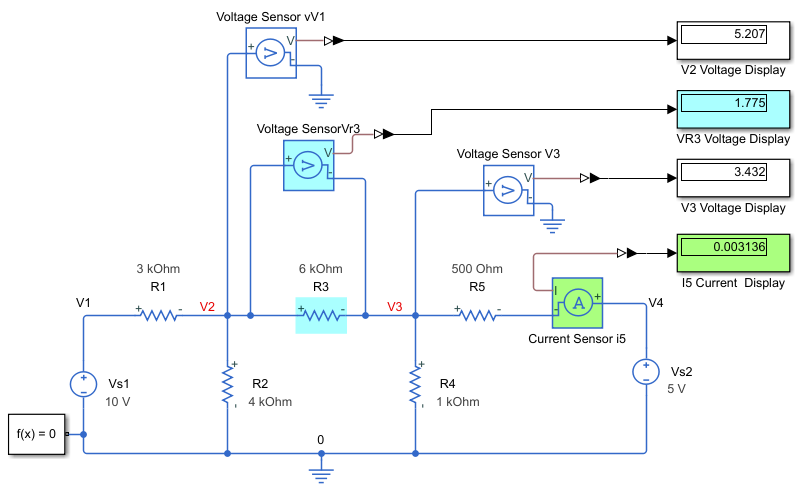

#### Exercise 1. Node analysis with voltage sources connected to reference node

Writing node analysis to find $$V_2, V_3$, voltage cross resistor $V_{R_5}$, and  current through $R_3$ and $R_5$. 

Solve the problem in MATLAB Script. Simulate the circuit in MATLAB Simulink to verify the results. 

                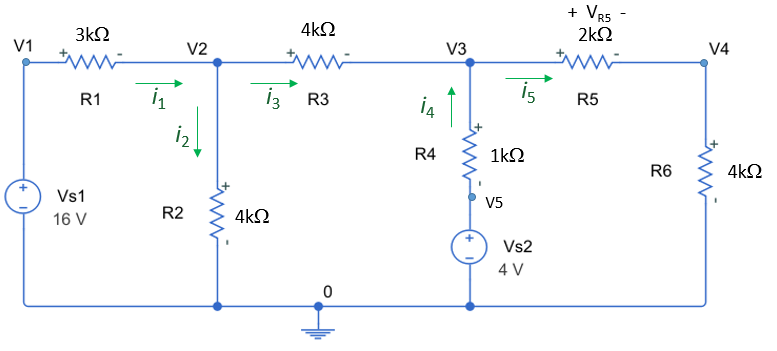

**Solution:**    

        Steps 1,2 and 3 is  given in the figure. Need to look at the figure above to find  any of the node voltages are known?

                           
$$V_1 =?V$$
  
$$V_5 =?V$$


        4.  Apply KCL at node 2 and 3.  Node 4 voltage V4 can be calculated by using voltage division after finding V3. So, we don't need to include it in our matrix equation to keep the matrix more simple.

        5. Write each of the branch currents in terms of node voltages using Ohm’s Law. Be careful about the polarities.

                        $i_1 =?$,      $i_2 =?$,     $i_3 =?$,      $i_4 =?$,   and       $i_5 = ?$

         6. Apply the branch currents equation to KCL at node 2 and 3 equations.

                 At node 2                

                 At Node 3           

        Node equation can be solved manually with some simple algebra. The equations can be combined in unknown variables and put into a matrix form 

                    
$$\left[ \begin{array} { c c } {? } & {?} \\ { ? } & {? } \end{array} \right] \left[ \begin{array} { l } { V _ 2 } \\ { V _ 3 } \end{array} \right] = \left[ \begin{array} { c } { ?} \\ {? } \end{array} \right]$$


        Using solution of inverse matrix, find the following 

            $V_2=?$,   $V_3=?$

            
$$V_{R_5}=?$$


            
$$i_3=?$$


            
$$i_5=?$$


u = symunit;
% Given

% Matrix AxV=b


% V2 = V(1);
% V2 = rewrite(V2,u.V)
% V3 = V(2)
% V3 = rewrite(V3,u.V)

% Find the voltage VR5 cross the resistor R5 , and current i3 and i5 as mA


% i3 = rewrite(i3,u.mA)
% i5 = rewrite(i5,u.mA)

Display each values in 4 significant decimal digits

% V2 = vpa(V2,5)
% V3 = vpa(V3,5)
% VR5 = vpa(VR5,5)
% i3 = vpa(i3,5)
% i5 = vpa(i5,5)

To check your matrix solution, you can solve this  exercise using MATLAB **solve** function 

% Given


% Known node voltage V1 and V2


% Unknown node voltage V2 and V3
% syms V2 V3;
% Node equation and solution
% [V2,V3] = solve(?? ,??);

% V2 = rewrite(V2,u.V)
% V3 = rewrite(V3,u.V)

% Find voltage VR5 cross resistor R5

% % Find Voltage  VR5,an currents i3, i5


Simulate  this exercise using MATLAB Simulink to chek your values. 

###         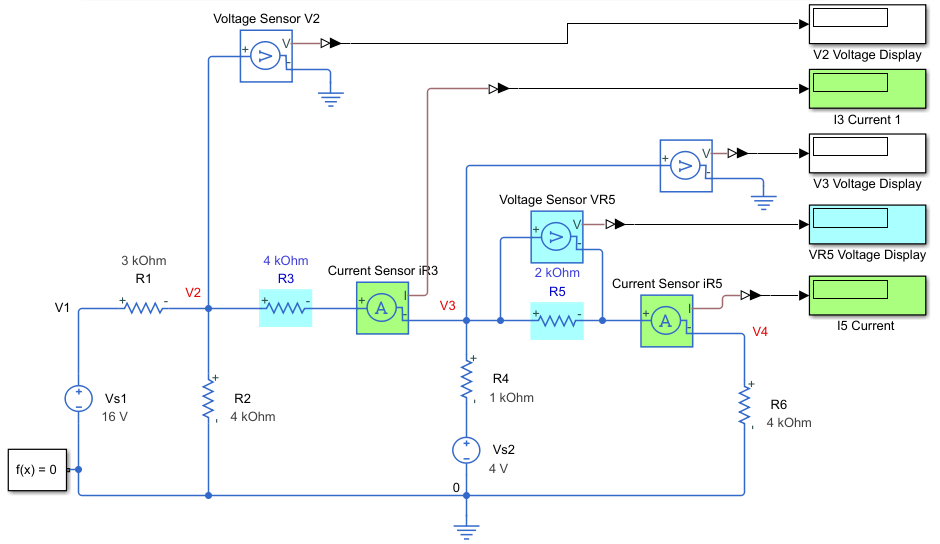

#### Example 2.  Node analysis with voltage sources connected to reference node and included current source

- Using node analysis to find node voltages $$V_2, V_3, V_4$, voltage $$V_{R_4}$ cross resistor  $R_1$ , and  current through $R_4$

- Find node voltages $$V_2, V_3, V_4$, and voltage $$V_{R_4}$ cross resistor  $R_1$,  current through $R_4$ when the voltage source $V_{s1}=32V$

- Find node voltages $$V_2, V_3, V_4$, and voltage $$V_{R_4}$ cross resistor  $R_1$,  current through $R_4$ when the current source $I_{s1}=4mA$

               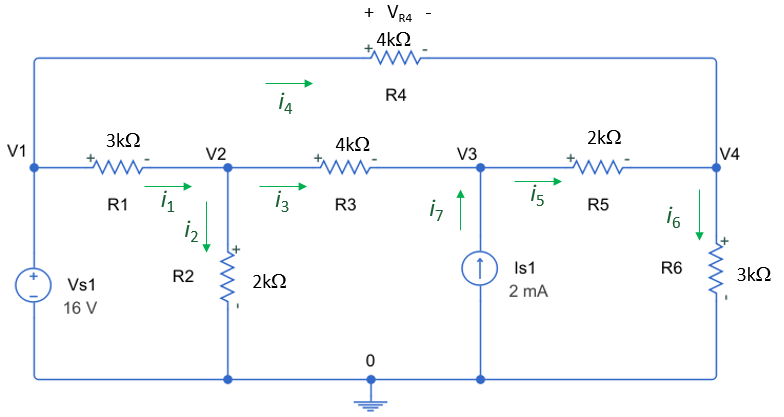

**Solution**

   Steps 1, 2, and 3 is  given in the figure above. Need to look at the figure to find  any of the nodes voltages are known?

                           
$$V_1 =V_{s1}=16V$$


    4.  Apply KCL at node 2 and 3, and 4

                                $i_1-i_2-i_3=0$ ,      $i_3+i_7+i_5=0$ , and   $i_4+i_5-i_6=0$

    5. Let's write each of the branch currents in terms of node voltages. This is done using Ohm’s Law and pay attention to the polarities.

                        $i_1 = \frac{V_{s1} -V_2 }{R_1}=\frac{16-V_2}{3k\Omega}$,      $i_2 = \frac{V_2 -0 }{R_2}=\frac{V_2}{2k\Omega}$,     $i_3 = \frac{V_2 -V_3 }{R_3}= \frac{V_2 -V_3 }{4k\Omega}$,   $i_4 = \frac{V_{s1} -V_4 }{R_4}= \frac{16-V_4 }{4k\Omega}$,       

                         $i_5 = \frac{V_3 -V_3 }{R_5}= \frac{V_3 -V_4 }{2 k\Omega}$,       $i_6 = \frac{V_4 -0 }{R_6}=\frac{V_4}{3k\Omega}$,  and     $i_7 = I_{s1}=2mA$

     6. Apply the branch currents equation to KCL equations at node 2 , 3, and 4.

                At node 2           $\frac{V_{s1}-V_2}{R_1}-\frac{V_2}{R_2}-\frac{V_2-V_3}{R_3}=0$     or   $\frac{16-V_2}{3k\Omega}-\frac{V_2}{2k\Omega}-\frac{V_2-V_3}{4k\Omega}=0$

                At Node 3           $\frac{V_2-V_3}{R_3}+I_{s1}-\frac{V_3-V_4}{R_5}=0$     or   $\frac{V_2-V_3}{4k\Omega}+2mA-\frac{V_3-V_4}{2k\Omega}=0$

                At Node 3           $\frac{V_{s1}-V_4}{R_4}+\frac{V_3-V_4}{R_5}-\frac{V_4}{R_6}=0$     or   $\frac{16-V_4}{4k\Omega}+\frac{V_3-V_4}{2k\Omega}-\frac{V_4}{3k\Omega}=0$

There are three unknowns and three equations. Use MATLAB solve function to find unknown voltages V2, V3, and V4  as follow. 

u = symunit;

% Given Values
Vs1 =16*u.V %Range 16V - 32 V

$$Vs1 = 16\,V$$

Is1 =2*u.mA %Range 2mA- 10mA

$$Is1 = 2\,\mathrm{mA}$$

R1 = 3*u.kOhm; R2 = 2*u.kOhm; R3 = 4*u.kOhm; R4 = 4*u.kOhm; R5 = 2*u.kOhm; R6 = 3*u.kOhm;

% Known node voltage V1 
V1 = Vs1;

% Unknown node voltages V2, V3, and V4
syms V2 V3 V4;

% Node equation and solution
[V2, V3, V4] = solve((Vs1-V2)/R1-V2/R2-(V2-V3)/R3==0, (V2-V3)/R3+Is1-(V3-V4)/R5==0, (Vs1-V4)/R4+(V3-V4)/R5-V4/R6==0) ;

% Access the solutions by addressing the elements of the structure.
V2 = rewrite(V2,u.V)

$$V2 = \frac{97}{13}\,V$$

V3 = rewrite(V3,u.V)

$$V3 = 11\,V$$

V4 = rewrite(V4,u.V)

$$V4 = \frac{114}{13}\,V$$

The voltage $$V_{R_4}$ cross resistor  $R_1$ , and  current through $R_4$ can be calculated by 

    $V_{R4}=V_1-V_4$  and   $i_{4}=\frac{V_{R4}}{R_4}$

In MATLAB:

% Find voltage  cross resistor R4 and currents through R4 and  
VR4=V1-V4

$$VR4 = \frac{94}{13}\,V$$

i4=VR4/R4;
i4 = rewrite(i4,u.mA)

$$i4 = \frac{47}{26}\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

 V2 = vpa(V2,5)

$$V2 = 7.4615\,V$$

 V3 = vpa(V3,5)

$$V3 = 11.0\,V$$

 V4 = vpa(V4,5)

$$V4 = 8.7692\,V$$

 i4 = vpa(i4,5)

$$i4 = 1.8077\,\mathrm{mA}$$

 VR4 = vpa(VR4,5)

$$VR4 = 7.2308\,V$$

**Alternative solution:**  Last equation in step 6 can be combined in unknown variables and put into a matrix form 

        $\left[ \begin{array} { c c } {-(\frac{1}{R_1} +\frac{1}{R_2}+\frac{1}{R_3})} & {\frac{1}{R_3} } & {0 } \\ {\frac{1}{R_3}} & {-(\frac{1}{R_3}+\frac{1}{R_5}) } &  {\frac{1}{R_5} } \\  {0} & {\frac{1}{R_5} } &  {-(\frac{1}{R_4}+\frac{1}{R_5}+\frac{1}{R_6}) } \end{array} \right] \left[ \begin{array} { l } { V _ 2 } \\ { V _ 3 } \\V_4 \end{array} \right] = \left[ \begin{array} { c } { -\frac{V_{s1}}{R_1}} \\ { -I_{s1} }\\ {-\frac{V_{s1}}{R_4} \end{array} \right]$ or    $\left[ \begin{array} { c c } {-(\frac{1}{3k} +\frac{1}{2k}+\frac{1}{4})} & {\frac{1}{4k} } & {0 } \\ {\frac{1}{4k}} & {-(\frac{1}{4k}+\frac{1}{2k}) } &  {\frac{1}{2k} } \\  {0} & {\frac{1}{2k} } &  {-(\frac{1}{4k}+\frac{1}{2k}+\frac{1}{3k}) } \end{array} \right] \left[ \begin{array} { l } { V _ 2 } \\ { V _ 3 } \\V_4 \end{array} \right] = \left[ \begin{array} { c } { -\frac{16}{3k}} \\ { -2mA }\\ {-\frac{16}{4k} \end{array} \right]$

Lets solve this matrix in MATLAB

u = symunit;

% Given Values
Vs1 =16*u.V %Range 12V - 32 V

$$Vs1 = 16\,V$$

Is1 =2*u.mA %Range 2mA- 10mA

$$Is1 = 2\,\mathrm{mA}$$

R1 = 3*u.kOhm; R2 = 2*u.kOhm; R3 = 4*u.kOhm; R4 = 4*u.kOhm; R5 = 2*u.kOhm; R6 = 3*u.kOhm;

% Known node voltage V1 
V1 = Vs1;

%Matrix AxV=b
A = [-(1/R1+1/R2+1/R3) 1/R3 0; 1/R3 -(1/R3+1/R5) 1/R5; 0 1/R5 -(1/R4+1/R5+1/R6)]

$$A = \left(\begin{array}{ccc} -\frac{13}{12}\,\frac{1}{\mathrm{k\Omega}} & \frac{1}{4}\,\frac{1}{\mathrm{k\Omega}} & 0\\ \frac{1}{4}\,\frac{1}{\mathrm{k\Omega}} & -\frac{3}{4}\,\frac{1}{\mathrm{k\Omega}} & \frac{1}{2}\,\frac{1}{\mathrm{k\Omega}}\\ 0 & \frac{1}{2}\,\frac{1}{\mathrm{k\Omega}} & -\frac{13}{12}\,\frac{1}{\mathrm{k\Omega}} \end{array}\right)$$

b = [-Vs1/R1; -Is1; -Vs1/R4]

$$b = \left(\begin{array}{c} -\frac{16}{3}\,\frac{V}{\mathrm{k\Omega}}\\ -2\,\mathrm{mA}\\ -4\,\frac{V}{\mathrm{k\Omega}} \end{array}\right)$$

V = A\b;

V2 = V(1); V2 = rewrite(V2,u.V)

$$V2 = \frac{97}{13}\,V$$

V3 = V(2); V3 = rewrite(V3,u.V)

$$V3 = 11\,V$$

V4 = V(3); V4 = rewrite(V4,u.V)

$$V4 = \frac{114}{13}\,V$$


% Find voltage  cross resistor R4  and Currents through R4
VR4 = V1-V4

$$VR4 = \frac{94}{13}\,V$$

i4 = VR4/R4;
i4 = rewrite(i4,u.mA)

$$i4 = \frac{47}{26}\,\mathrm{mA}$$

Display each values in  decimal digits

 V2 = vpa(V2,5)

$$V2 = 7.4615\,V$$

 V3 = vpa(V3,5)

$$V3 = 11.0\,V$$

 V4 = vpa(V4,5)

$$V4 = 8.7692\,V$$

 i4 = vpa(i4,5)

$$i4 = 1.8077\,\mathrm{mA}$$

 VR4 = vpa(VR4,5)

$$VR4 = 7.2308\,V$$

Finally, we find the following values for (1) :    $V_2=7.4615V$,   $V_3=11.0 V$, $V_4=8.7692 V$,  $V_{R_4}=V_{s1}-V_4=11-8.77=7.2308V$  and  $i_4=1.8077 mA$

 Circuit simulation using MATLAB Simulink [./Simulink\Example_2.slx](matlab:open('./Simulink\Example_2.slx'))

### 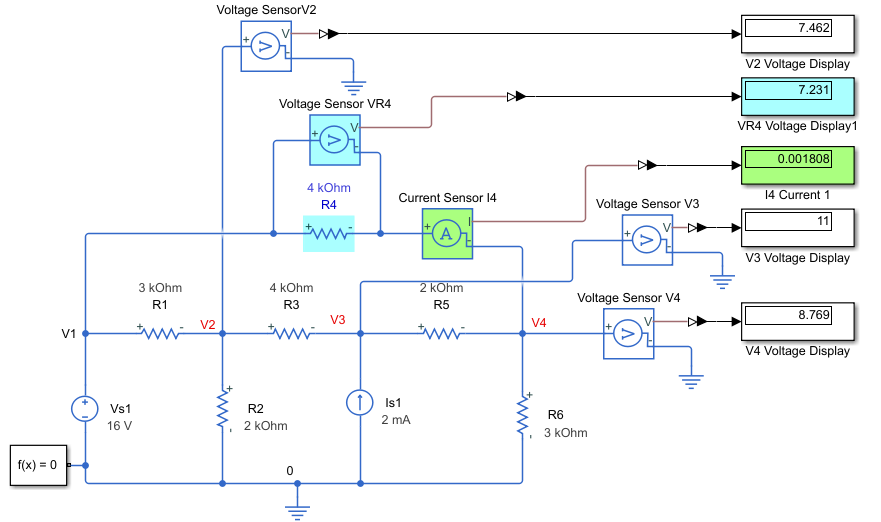

#### Exercise 2:  Node anaysis with voltage sourses connected to reference node and included current source

       Using node analysis to find $$V_2, V_3, V_4$, and voltage $$V_{R_4}$ cross resistor  $R_4$ , and  currents  $i_3 $ and $i_4 $.

       Solve the problem in MATLAB Script. Simulate the circuit in MATLAB Simulink to verify the results. 

            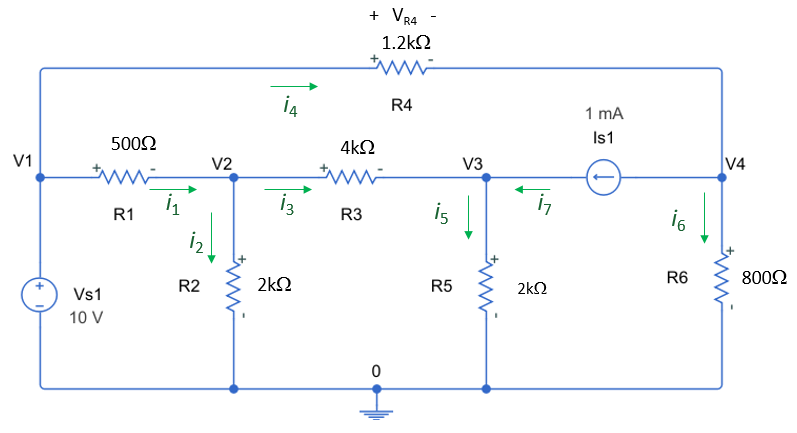

**Solution**

  Steps 1,2 and 3 is  given in the figure. Look at the figure above to find  any of the nodes voltages are known?

                
$$$V_1=?V$$
           

   4.  Apply KCL at node 2 and 3, and 4

   5. Let's write each of the branch currents in terms of node voltages. This is done using Ohm’s Law, but you have to be careful about the polarities.

   6. Apply the branch currents equation to KCL equations at node 2 , 3, and 4.

                At node 2          

                At Node 3          

                At Node 3           

Write it in matrix form 

Solve the matrix in MATLAB

u = symunit;
% Given
%??

% Known node voltage V1 
% ??

% Matrix AxV=b
% ??

% V2 = rewrite(V2,u.V)
% V3 = rewrite(V3,u.V)
% V4 = rewrite(V4,u.V)

% Find voltage  cross resistor R4  and Currents i3, and i4
% ??
% Display each values in  decimal digits
% ??

   To check your matrix solution, you can solve this exercise using MATLAB **solve** function 

u = symunit;
% Given
% ??

%Known node voltage 
% ??

%Unknown node voltage 
syms V2 V3 V4;
% Node equation and solution
% ??

%fprintf('V2 = %6.3f V \n',V2);
%fprintf('V3 = %6.3f V \n',V3);
%fprintf('V4 = %6.3f V \n',V4);

% Find voltage  cross  R4 and Currents i3 and i4 
% ??
% Display each values in  decimal digits
% ??

Simulate  this exercise using MATLAB Simulink to chek your values. 

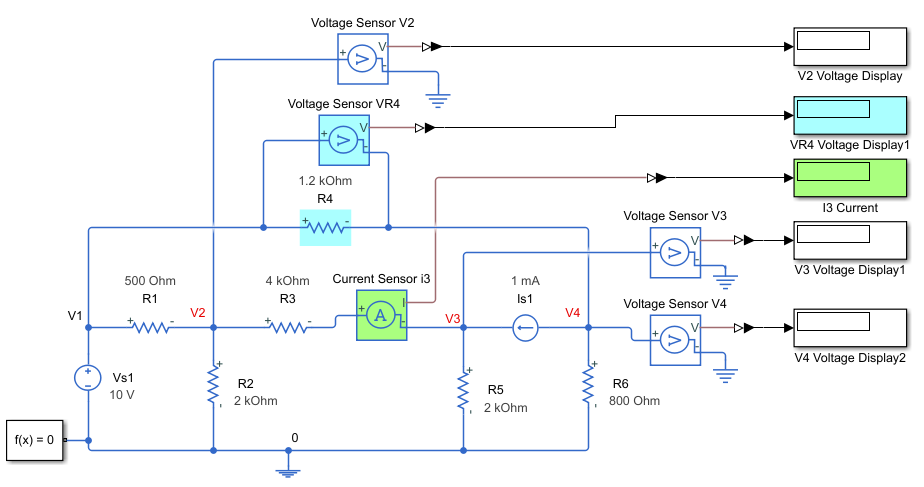

### **Case 2 :** A voltage source is connected between the nonreference nodes (**Supernode)**

If the voltage source is connected between nonreferencenodes, these node voltages and the current through the voltage source are not known, We combine these  two nonreferencenodes forms as supernode. Then the node equation for this supernode and additional KVL  equation, commonly referred to as a constraint equation relating the two node voltages, can be obtained by representing the voltage source as a potential drop between the two nodes.  Using both KCL and KVL to determine the node voltages.    

#### Example 3. Node analysis with voltage sources connected between two nonreference nodes

Writing node analysis to find node voltages $$V_2, V_3$, voltage $V_{R3}$ cross resistor  $R_3$, and  current $i_5$

                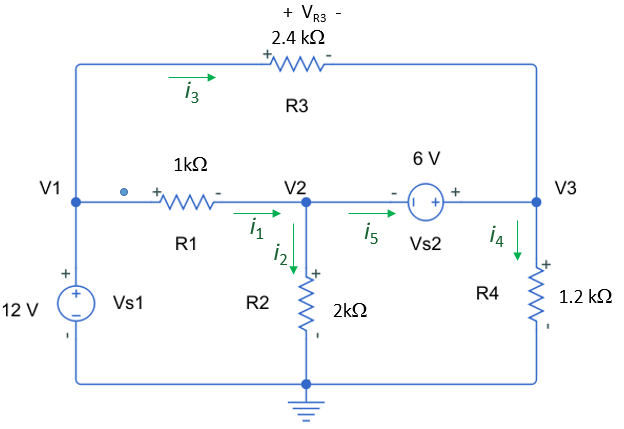

   **Solution:**      Look at the figure above to find  any of the nodes voltages are known?

                           
$$V_1 =V_{s1}=12V$$
  

     Since we don't know the current through $V_{s2}$, we define a supernode  cover node 2 and 3, apply KCL to  the supernode, and write additional KVL  equation in loop 1

            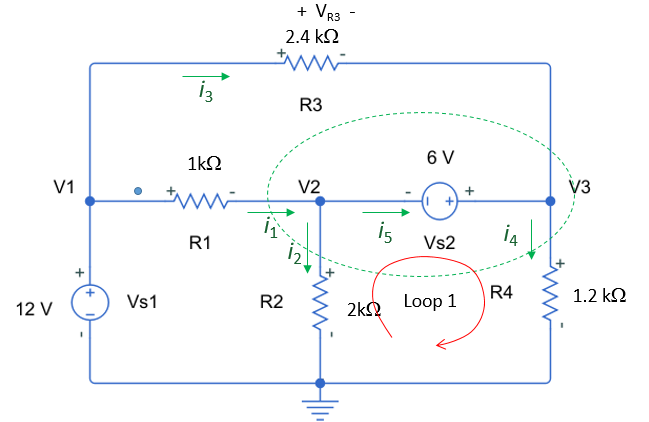

                      Supernode :           $i_1-i_2+i_3-i_4=0$      

                       Loop 1 :            $-V_2-V_{s2}+V_3=0$    or      $-V_2+V_3=V_{s2}$        which is  $-V_2+V_3=6$

        Let's write each of the branch currents in terms of node voltages. This is done using Ohm’s Law with pay attention to the polarities.

                        $i_1 = \frac{V_{s1} -V_2 }{R_1}=\frac{12-V_2}{1k\Omega}$,      $i_2 = \frac{V_2 -0 }{R_2}=\frac{V_2}{2k\Omega}$,     $i_3 = \frac{V_{s1} -V_3 }{R_3}= \frac{12 -V_3 }{2.4k\Omega}$,  

                         $i_4 = \frac{V_3  }{R_4}= \frac{V_3 }{1.2k\Omega}$,           $i_1 -i_2-i_5=0$ (for $i_5$ )   which is   $i_5=i_1 -i_2$

         Apply the branch currents equation to KCL equations at supernode.

          At supernode           $\frac{V_{s1}-V_2}{R_1}-\frac{V_2}{R_2}+\frac{V_{s1}-V_3}{R_3}-\frac{V_3}{R_4}=0$     or    $\frac{12-V_2}{R_1}-\frac{V_2}{R_2}+\frac{12-V_3}{R_3}-\frac{V_3}{R_4}=0$

     There are two unknowns and two equations, one form supernode and one from loop.  Use MATLAB **solve** function to find unknown voltages V2, and V3  as follow.

u = symunit;
% Given
Vs1 = 12*u.V; Vs2 = 6*u.V; R1=1*u.kOhm;R2=2*u.kOhm; R3=2.4*u.kOhm; R4 = 1.2*u.kOhm;

% Known node voltage V1 
V1 = Vs1;

% Unknown node voltage V2 and V3
syms V2 V3;
% Node equation and solution
[V2,V3]=solve((Vs1-V2)/R1-V2/R2+(Vs1-V3)/R3-V3/R4==0, -V2-Vs2+V3==0) ;

V2 = rewrite(V2,u.V)

$$V2 = \frac{38}{11}\,V$$

V3 = rewrite(V3,u.V)

$$V3 = \frac{104}{11}\,V$$

The voltage  $V_{R3}$ cross resistor $R_3$  can be calculated 

$V_{R3}=V_1-V_3$ and

 To find current $i_5$ through  the $V_{s2}$, we need to find $i_1$ and $i_2$. 

 $i_1 = \frac{V_{s1} -V_2 }{R_1}=\frac{12-V_2}{1k\Omega}$,   $i_2 = \frac{V_2 }{R_2}=\frac{V_2}{2k\Omega}$

Then aooly KCL for node 2 

$i_1 -i_2-i_5=0$   or  $i_5=i_1-i_2$

% Find Voltage VR3 cross the resistor R3 and Current i5
VR3 = V1-V3

$$VR3 = \frac{28}{11}\,V$$

i1 = (Vs1-V2)/R1;
i2 = V2/R2;
i5 = i1-i2;
i5 = rewrite(i5,u.mA)

$$i5 = \frac{75}{11}\,\mathrm{mA}$$

 Display each values in 4 significant decimal digits

V2 = vpa(V2,5)

$$V2 = 3.4545\,V$$

V3 = vpa(V3,5)

$$V3 = 9.4545\,V$$

VR3 = vpa(VR3,5)

$$VR3 = 2.5455\,V$$

i5 = vpa(i5,5)

$$i5 = 6.8182\,\mathrm{mA}$$

**Alternative solution:**   The spernode equation and loop 1 equation can be combined in unknown variables and put into a matrix form  

                  $\left[ \begin{array} { c c } { -(\frac{1}{R_1}+\frac{1}{R_2}) } & {-(\frac{1}{R_3} +\frac{1}{R_4})} \\ { -1} & {1 } \end{array} \right] \left[ \begin{array} { l } { V _ 2 } \\ { V _ 3 } \end{array} \right] = \left[ \begin{array} { c } { -(\frac{1}{R_1}+\frac{1}{R_3})V_{s1}} \\ {V_{s2}} \end{array} \right]$  or            $\left[ \begin{array} { c c } { -(\frac{1}{1k}+\frac{1}{2k}) } & {-(\frac{1}{2.4k} +\frac{1}{1.2k})} \\ { -1} & {1 } \end{array} \right] \left[ \begin{array} { l } { V _ 2 } \\ { V _ 3 } \end{array} \right] = \left[ \begin{array} { c } { -(\frac{1}{1k}+\frac{1}{2.4k})V_{s1}} \\ {V_{s2}} \end{array} \right]$

Lets solve this matrix in MATLAB

u = symunit;

% Given
% Given
Vs1 = 12*u.V; Vs2 = 6*u.V; R1=1*u.kOhm;R2=2*u.kOhm; R3=2.4*u.kOhm; R4 = 1.2*u.kOhm;

% Known node voltage V1 
V1 = Vs1;

%Matrix AxV=b
A=[-(1/R1+1/R2) -(1/R3+1/R4); -1 1]

$$A = \left(\begin{array}{cc} -\frac{3}{2}\,\frac{1}{\mathrm{k\Omega}} & -\frac{5}{4}\,\frac{1}{\mathrm{k\Omega}}\\ -1 & 1 \end{array}\right)$$

b=[-(1/R1+1/R3)*Vs1; Vs2];
V=A\b;

V2=V(1); V2 = rewrite(V2,u.V)

$$V2 = \frac{38}{11}\,V$$

V3=V(2); V3 = rewrite(V3,u.V)

$$V3 = \frac{104}{11}\,V$$


% Find Voltage VR3 cross the resistor R3 and Current i5
VR3 = V1-V3

$$VR3 = \frac{28}{11}\,V$$

i1 = (Vs1-V2)/R1;
i2 = V2/R2;
i5 = i1-i2;
i5 = rewrite(i5,u.mA)

$$i5 = \frac{75}{11}\,\mathrm{mA}$$

 Display each values in 4 significant decimal digits

V2 = vpa(V2,5)

$$V2 = 3.4545\,V$$

V3 = vpa(V3,5)

$$V3 = 9.4545\,V$$

VR3 = vpa(VR3,5)

$$VR3 = 2.5455\,V$$

i5 = vpa(i5,5)

$$i5 = 6.8182\,\mathrm{mA}$$

Finally, we find the following values :    $V_2=3.4545V$,   $V_3=9.4545 V$, $V_{R3}=2.5455 V$, and  $i_5=6.8182 mA$

Circuit simulation is given in the following MATLAB Simulink  [./Simulink\Example_3.slx](matlab:open('./Simulink\Example_3.slx'))

###     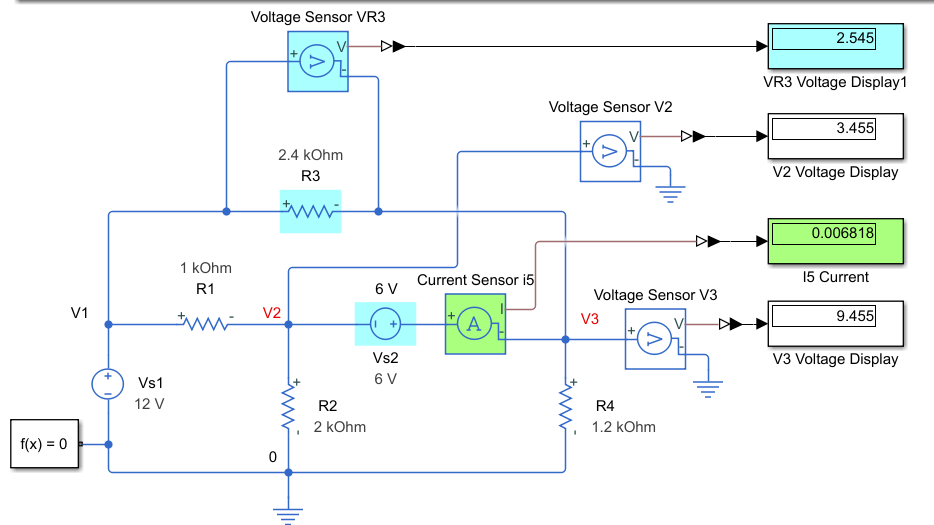

#### Exercise 3. Node anaysis with voltage sourses connected between two nonreference nodes 

Using node analysis to find $$V_1, V_2, V_3$, and voltage $$V_{R_5}$ cross resistor  $R_5$ , and  current  $i_6 $ . Solve the problem in MATLAB Script. Simulate the circuit in MATLAB Simulink to verify the results. 

                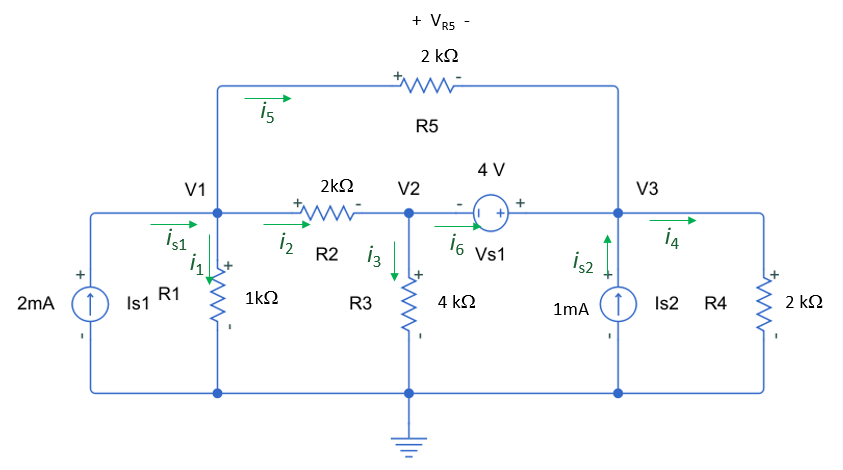

**Solution**

       Step 1,2,and 3 done. Look at the figure above to find  any of the nodes voltages are known?

        4.  Write KCL node equation for node 1. Since we dont know the current through $V_{s1}$, We define a supernode  cover node 2 and 3, apply KCL to  the supernode, and write additional KVL  cover $V_{s1}$

        5. Let's write each of the branch currents in terms of node voltages. This is done using Ohm’s Law, but you have to be careful about the polarities.

         6. Apply the branch currents equation to KCL equations at node 2 , 3, and 4.

                At node 1          

                Supernode                   

Write in a matrix form 

   write it  in MATLAB to find V1, V2 and V3

u = symunit;

% Given
% ??

% Known any node voltage 
% ??

%Matrix AxV=b
% A = ??;
% b = ??;
% ??

% V1=V(1); V2 = rewrite(V2,u.V)
% V2=V(2); V3 = rewrite(V3,u.V)
% V3=V(3); V3 = rewrite(V3,u.V)

Write a equation for  voltage  $V_{R5}$ cross resistor $R_5$   

??

 Find the currents $i_2$ and $i_3$to calculate current $i_6$ through  $V_{s1}$, 

% Find Voltage VR5 cross the resistor R5 and Current i6 through Vs1

% VR5 = ??
% i2 = ??;
% i3 = ??;
% i6 = ??;
% i6 = rewrite(i6,u.mA)

 Display each values in decimal digits

% V1 = vpa(V1,5)
% V2 = vpa(V1,5)
% V3 = vpa(V3,5)
% VR5 = vpa(VR5,5)
% i6 = vpa(i6,5)

   To check your matrix solution, you can solve this exercise using MATLAB **solve** function 

u = symunit;
% Given


% Known node voltage 


% Unknown node voltage 
syms ;

Your symbolic variables are:

A    G    Is1  R1   R2   R3   R4   R5   R6   V    V1   V2   V3   V4   VR3  VR4  Vs1  Vs2  b    i1   i2   i3   i4   i5                                                                                                                 



% Node equation and solution
% [V1,V2,V3] = solve(?? ,??,??);

% V1 = rewrite(V1,u.V)
% V2 = rewrite(V2,u.V)
% V3 = rewrite(V3,u.V)

% Find Voltage VR5 cross the resistor R5 and Current i6 through Vs1


Simulate  this exercise using MATLAB Simulink to chek your values. 

### 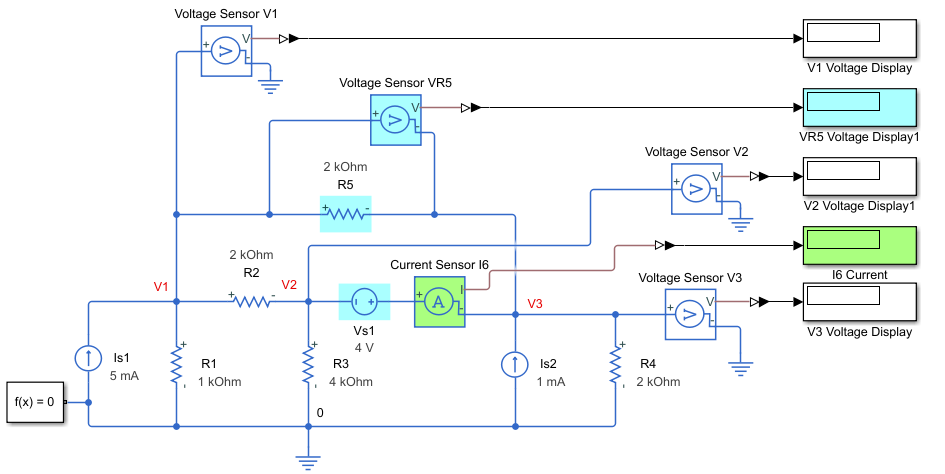

#### Example 4 Node analysis with dependent voltage sources connected between two nonreference nodes 

- Using node analysis to find node voltages $$V_1, V_2, V_3$, 

- Find node voltages $$V_1, V_2, V_3$, when the current  source $I_{s1}=12mA$

- Find node voltages $$V_1, V_2, V_3$,  when the dependent voltage source coefficient  changed to 1000        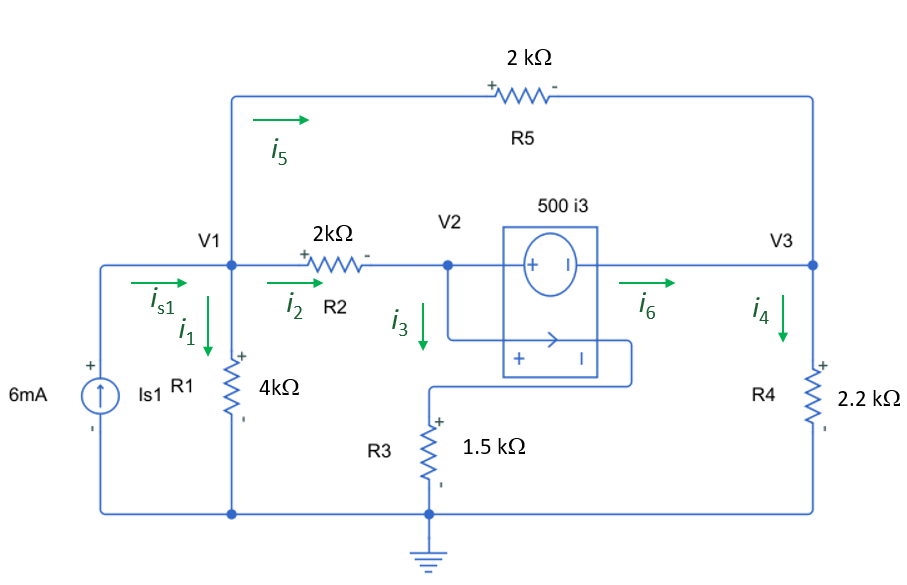

**Solution:**  Steps 1,2 and 3 is  given in the figure. Need to look at the figure above to find  any of the nodes voltages are known?

                           None

4.   KCL for node 1 :    $i_{s1}-i_1-i_2-i_5=0$      

Since we don't know the current through dependent voltage source , We define a supernode  cover node 2 and 3, apply KCL to  the supernode, and write additional KVL  equation in loop 1

            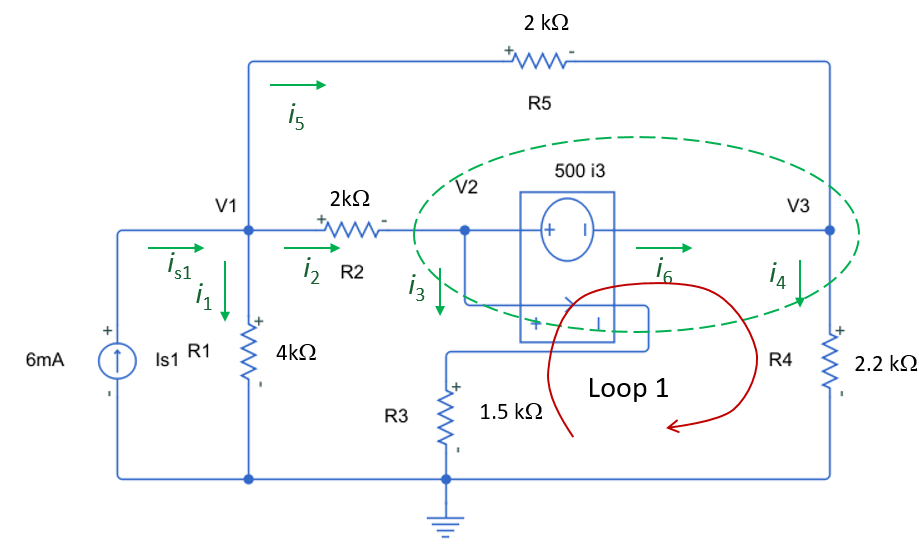

                      Supernode :           $i_2-i_3-i_4+i_5=0$      

                        Loop 1 :            $-V_2+500i_3+V_3=0$    

      5. Let's write each of the branch currents in terms of node voltages. This is done using Ohm’s Law using polarities.

                        $i_1 = \frac{V_1 }{R_1}=\frac{V_1}{4k\Omega}$,      $i_2 = \frac{V_1 -V_2 }{R_2}=\frac{V_1-V_2}{2k\Omega}$,     $i_3 = \frac{V_2 }{R_3}= \frac{1V_2 }{1.5k\Omega}$,  

                         $i_4 = \frac{V_3  }{R_4}= \frac{V_3 }{21.2k\Omega}$,       $i_4 = \frac{V_1-V_3  }{R_5}= \frac{V_1-V_3 }{2k\Omega}$    

              To find  $i_5$, we can write KCL for node 2, or 3 : $i_2 -i_3-i_5=0$ (for $i_5$ )   or  $i_6+i_5-i_4=0$

       6. Apply the branch currents equation to KCL equations at supernode.

                 At Node 1                 $i_{s1}-\frac{V_1}{R_1}-\frac{V_1-V_2}{R_2}-\frac{V_1-V_3}{R_5}=0$

                At supernode           $\frac{V_1-V_2}{R_2}-\frac{V_2}{R_3}-\frac{V_3}{R_4}+\frac{V_1-V_3}{R_5}=0$    

                and Loop 1                       $-V_2+500\frac{V_2}{R_3}+V_3=0$  

Apply these  three equations in MATLAB. Use MATLAB **solve** function to find unknown voltages V1, V2, and V3 as follow

u = symunit;

% Given
Is1= 6*u.mA   %Range 2mA- 10mA

$$Is1 = 6\,\mathrm{mA}$$

G=500 *u.Ohm      %Dependent source gain range 500 -  1000

$$G = 500\,\Omega$$

R1 = 4*u.kOhm; R2 = 2*u.kOhm; R3 = 1.5*u.kOhm; R4 = 2.2*u.kOhm; R5 = 2*u.kOhm; 

%Known node voltage . 

%Unknown node voltage V2 and V3
syms V1 V2 V3;
%Node equation and solution
[V1,V2,V3] = solve(Is1-(V1)/R1-(V1-V2)/R2-(V1-V3)/R5==0, (V1-V2)/R2-V2/R3-V3/R4+(V1-V3)/R5==0, -V2+G*V2/R3+V3==0) ;

% Access the solutions by addressing the elements of the structure.
V1 = rewrite(V1,u.V)

$$V1 = \frac{952}{125}\,V$$

V2 = rewrite(V2,u.V)

$$V2 = \frac{528}{125}\,V$$

V3 = rewrite(V3,u.V)

$$V3 = \frac{352}{125}\,V$$

    Display each values in decimal digits

V1 = vpa(V1,5)

$$V1 = 7.616\,V$$

V2 = vpa(V2,5)

$$V2 = 4.224\,V$$

V3 = vpa(V3,5)

$$V3 = 2.816\,V$$

**Alternative solution:**  Last tree equations can be combined in unknown variables and put into a matrix form 

                    
$$\left[ \begin{array} { c c } {-(\frac{1}{R_1} +\frac{1}{R_2}+\frac{1}{R_5})} & {\frac{1}{R_2} } & {\frac{1}{R_5} } \\ {\frac{1}{R_2}+\frac{1}{R_5}} & {-(\frac{1}{R_2}+\frac{1}{R_3}) } &  {-(\frac{1}{R_4}+\frac{1}{R_5}) } \\  {0} & {-1+\frac{500}{R_3} } &  {1} \end{array} \right] \left[ \begin{array} { l } { V _ 1 } \\ { V _ 2 } \\V_3 \end{array} \right] = \left[ \begin{array} { c } { -I_{s1}} \\ {0 }\\ {0} \end{array} \right]$$
   

Lets solve this matrix in MATLAB

u = symunit;

% Given
Is1= 6*u.mA   %Range 2mA- 10mA

$$Is1 = 6\,\mathrm{mA}$$

G=500*u.Ohm   %Dependent source gain range 500 -  1000

$$G = 500\,\Omega$$

R1 = 4*u.kOhm; R2 = 2*u.kOhm; R3 = 1.5*u.kOhm; R4 = 2.2*u.kOhm; R5 = 2*u.kOhm; 

%Matrix AxV=b
A=[-(1/R1+1/R2+1/R5) 1/R2 1/R5; 1/R2+1/R5 -(1/R2+1/R3) -(1/R4+1/R5); 0 -1+G/R3 1]

$$A = \left(\begin{array}{ccc} -\frac{5}{4}\,\frac{1}{\mathrm{k\Omega}} & \frac{1}{2}\,\frac{1}{\mathrm{k\Omega}} & \frac{1}{2}\,\frac{1}{\mathrm{k\Omega}}\\ \frac{1}{\mathrm{k\Omega}} & -\frac{7}{6}\,\frac{1}{\mathrm{k\Omega}} & -\frac{21}{22}\,\frac{1}{\mathrm{k\Omega}}\\ 0 & \frac{1000}{3}\,\frac{\Omega }{\mathrm{k\Omega}}-1 & 1 \end{array}\right)$$

b=[-Is1; 0; 0]

$$b = \left(\begin{array}{c} -6\,\mathrm{mA}\\ 0\\ 0 \end{array}\right)$$

V=A\b;

V1=V(1); V1 = rewrite(V1,u.V)

$$V1 = \frac{952}{125}\,V$$

V2=V(2); V2 = rewrite(V2,u.V)

$$V2 = \frac{528}{125}\,V$$

V3=V(3); V3 = rewrite(V3,u.V)

$$V3 = \frac{352}{125}\,V$$

    Display each values in decimal digits

V1 = vpa(V1,5)

$$V1 = 7.616\,V$$

V2 = vpa(V2,5)

$$V2 = 4.224\,V$$

V3 = vpa(V3,5)

$$V3 = 2.816\,V$$

Finally, we find the following values :    $V_1=7.616V$,   $V_2=4.224 V$, and $V_3=2.816 V$

Circuit simulation using MATLAB Simulink  [./Example_4.slx](matlab:open('./Example_4.slx'))

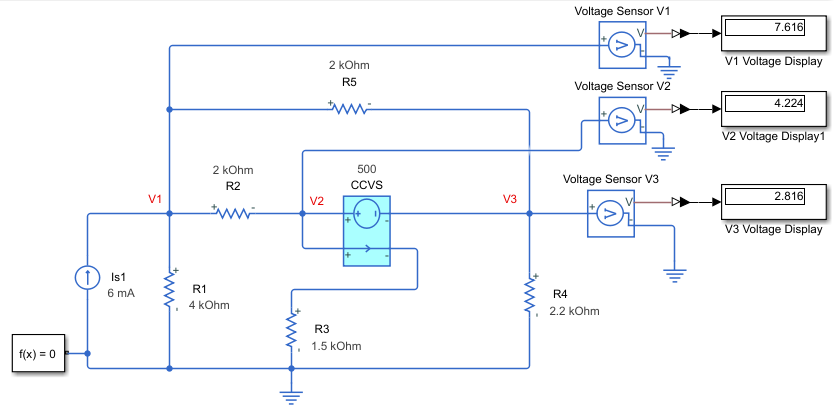

#### Exercise 4. Node analysis with dependent voltage sources connected between two nonreference nodes

- Using node analysis to find node voltages $$V_1, V_2, V_3$, and $$V_4$.

- Find node voltages $$V_1, V_2, V_3$, and $$V_4$ when the current  source $I_{s1}=20mA$

- Find node voltages $$V_1, V_2, V_3$,  and $$V_4$ when the dependent voltage source coefficient  changed to 100.

Solve the problem in MATLAB Script. Simulate the circuit in MATLAB Simulink to verify the results. 

                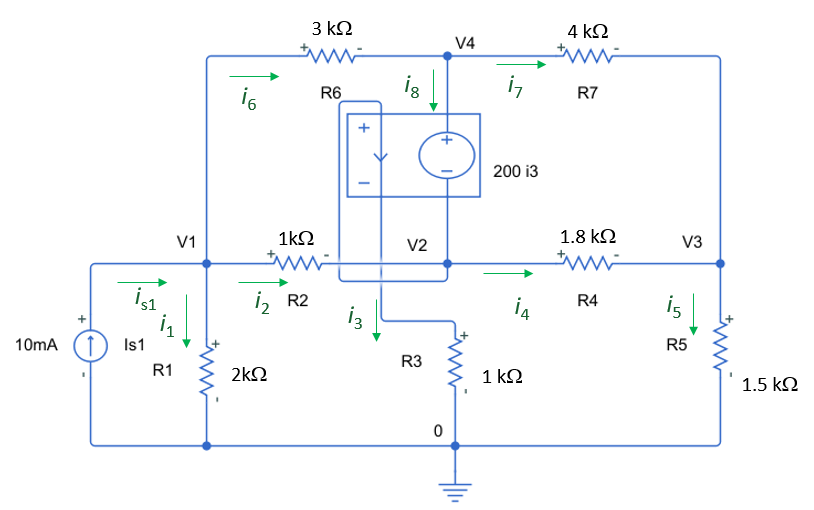

**Solution**

  Look at the figure above to find  any of the nodes voltages are known?

                           ?

 4.  KCL for node 1 : ?  

      KCL for node 3 : ?  

Since we don't know the current through dependent voltage source, we define a supernode  cover node 2 and 4, apply KCL to  the supernode, and write additional KVL equation that cover dependent source.

                      Supernode :          ?      

                        Loop 1 :            ?    

     5. Let's write each of the branch currents in terms of node voltages. This is done using Ohm’s Law, but you have to be careful about the polarities.

                        $i_1 =?$,      $i_2 = ?$,     $i_3 = ?$,  $i_4 =?$,       $i_4 =?$   , $i_5 =?$,       $i_6 =?$  , $i_7 =?$

                 If we need to  find  $i_8$, we can write KCL for node 2, or 4 : after find other branh current  

      6. Apply the branch currents equation to KCL equations at supernode.

                 At Node 1   : ?

                 At Node 3   : ?                 

                At supernode : ?            

                and Loop 1    :?  

      Write in  matrix form 

    Lets solve this matrix in MATLAB

u = symunit;

%Given
Is1= 10*u.mA   %Range 10mA- 20mA

$$Is1 = 10\,\mathrm{mA}$$

G=400 *u.Ohm    %Dependent source gain range 100 -  400

$$G = 400\,\Omega$$

% R1=?;   R2=?;  ???

% Known node voltage ? 

% Matrix AxV=b
% A=[? ?]
% b=[? ?]
% V=A\b;
% 
% V1=V(1); V1 = rewrite(V1,u.V)
% V2=V(2); V2 = rewrite(V2,u.V)
% V3=V(3); V3 = rewrite(V3,u.V)
% V4=V(4); V4 = rewrite(V4,u.V)

    Display each values in decimal digits

% V1 = vpa(V1,5)
% V2 = vpa(V2,5)
% V3 = vpa(V3,5)
% V4 = vpa(V4,5)

To check your matrix solution, you can solve this exercise using MATLAB **solve** function 

u = symunit;
%Given
%Given
Is1= 10*u.mA   %Range 10mA- 20mA

$$Is1 = 10\,\mathrm{mA}$$

G=400 *u.Ohm    %Dependent source gain range 100 -  400

$$G = 400\,\Omega$$

% R1=?;   R2=?;  ???

% Known node voltage ? 


% Unknown node voltage 
% syms V1 V2 V3 V4;
% Node equation and solution
% [V1, V2, V3]=solve (??,??,??;

% Access the solutions by addressing the elements of the structure.
% V1 = rewrite(V1,u.V)
% V2 = rewrite(V2,u.V)
% V3 = rewrite(V3,u.V)
% V4 = rewrite(V4,u.V)

    Display each values in decimal digits

% V1 = vpa(V1,5)
% V2 = vpa(V2,5)
% V3 = vpa(V3,5)
% V4 = vpa(V4,5)

Simulate  this exercise using MATLAB Simulink to chek your values. 

### 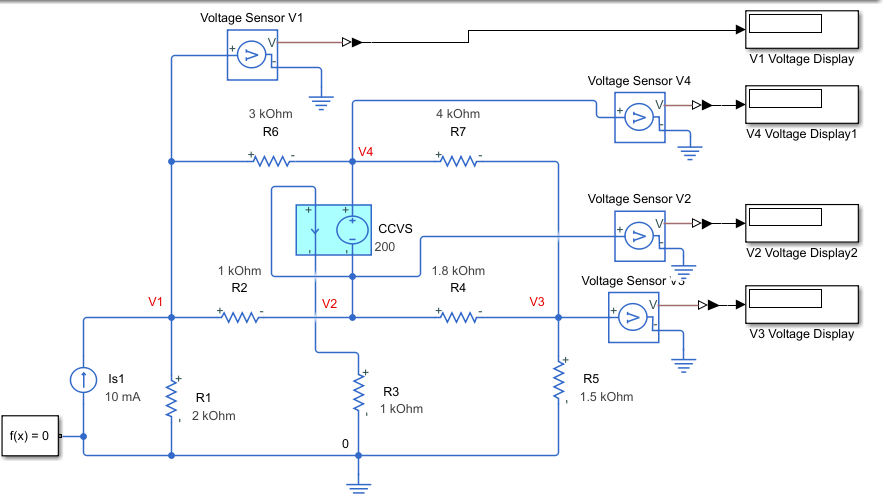

## References/Additional Info

***Electric Circuits***, James Kang, 1st ed. Cengage Learning, 2018